## Introduction

#### What is the main theme? Why is it important?

The purpose of this project is to study the impact of climate on glaciers through modeling the kinematics and mechanics of ice flow. It is important because glaciers are sensitive to slight changes in climate. We can infer past climate based on how glaciers molded landscapes and changed vegetation over time. To understand these changes, we need to understand how glaciers respond to changes in climate.

#### What observations, models, etc are used by others that are different from what you are doing in the project?

## Equations

#### What are the fundamental physical/chemical/etc. processes? 

This model is based on the concept that a glacier is a one-dimensional flow system which is continuously receiving or losing new material. **More glacier info??** We are modeling a kinematic wave equation as it pertains to ice flow. A wave in this sense refers to a point carrying a specified property (q) moving through a medium at a speed different than the medium itself.

#### Relevant equations and potentially where they come from (i.e. how are they derived)

Kinematic wave equation (eqn 4 in Nye 1960)

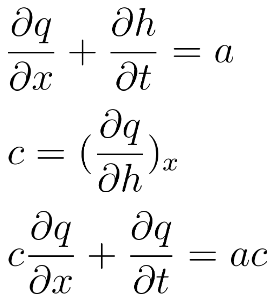

this is the surface slope as a function of (x, t) downhill in x direction beta is the slope of inclination


$$\[ \alpha = \beta - \frac{\partial{h}}{\partial{x}} \]$$


the paper also defines a value for u- this value is based on a  pre established tou value of rho*g*sin(alpha)


$$\[ u = \frac{\rho g h sin(\alpha)} {A}^{m} \]$$


where rho is density, h is height, g is gravity and alpha is the same as defined above.

the paper also defines at a(x,t) based on seaonal and or climate driven accumulation


$$\[ a(x,t) = a_0(x) + a_1(x,t) \]$$


they go on to say that a0 will be the avergaed rate of accumulation over a full year(net accumulation) and a1 will be the departure from a0(produced by seaonal or climatic changes

#### Describe all terms and parameters. 

q = volume of ice passing a given point in unit time (1 / unit breadth)

a = accumulation rate at surface (positive = addition of ice due to snowfall or avalanche, negative = melting or evaporation of ice)

c = velocity (but not velocity of the ice itself, which is u = q/h)

#### Describe any assumptions being made

We assume the volume and velocity (c) of the glacier are constant. Some simulations run assume accumulation is constant, and some assume accumulation oscillates a sine function throughout the year.

## Numerical Methods

#### Describe the numerical methods used.

Forward Euler

#### Why did you choose to use these methods

len =      2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51


a_rate = -5.0000e-06

div = 12

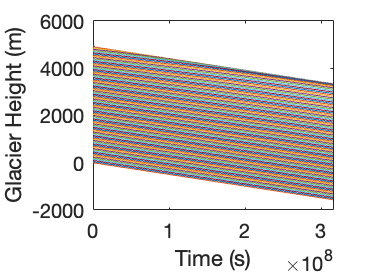

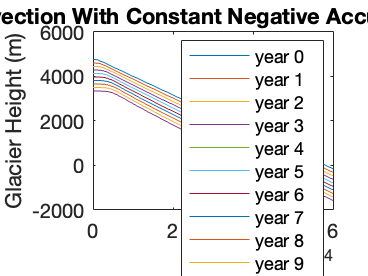

H = 	1.0e+03 *

    5.0000    4.8869    4.8829    4.8689    4.8558    4.8427    4.8296    4.8164    4.8033    4.7901    4.7770    4.7639    4.7507    4.7376    4.7244    4.7113    4.6982    4.6850    4.6719    4.6587    4.6456    4.6325    4.6193    4.6062    4.5930    4.5799    4.5668    4.5536    4.5405    4.5273    4.5142    4.5011    4.4879    4.4748    4.4616    4.4485    4.4354    4.4222    4.4091    4.3959    4.3828    4.3697    4.3565    4.3434    4.3302    4.3171    4.3040    4.2908    4.2777    4.2645
    4.9000    4.8960    4.8820    4.8690    4.8558    4.8427    4.8296    4.8164    4.8033    4.7901    4.7770    4.7639    4.7507    4.7376    4.7244    4.7113    4.6982    4.6850    4.6719    4.6587    4.6456    4.6325    4.6193    4.6062    4.5930    4.5799    4.5668    4.5536    4.5405    4.5273    4.5142    4.5011    4.4879    4.4748    4.4616    4.4485    4.4354    4.4222    4.4091    4.3959    4.3828    4.3697    4.3565    4.3434    4.3302    4.3171    4.3040    4.2908   

% Forward Euler

% we assume that spacial changes negligable

a_init = .000005; %m/s

a_rate = a_init.*sin((t.*pi)./(500) + 0.03); 

H = Up_euler(-.000005, "Constant Negative")

len =      2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51


a_rate = 5.0000e-06

div = 12

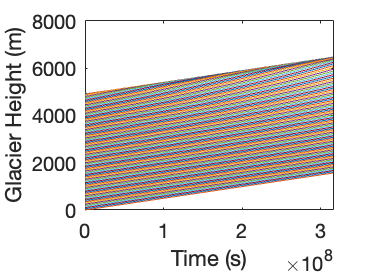

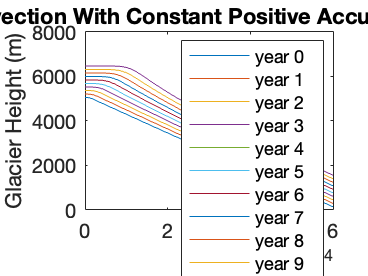

H = 	1.0e+03 *

    5.0000    4.9131    4.9354    4.9477    4.9609    4.9741    4.9872    5.0004    5.0135    5.0266    5.0398    5.0529    5.0661    5.0792    5.0923    5.1055    5.1186    5.1318    5.1449    5.1580    5.1712    5.1843    5.1975    5.2106    5.2237    5.2369    5.2500    5.2632    5.2763    5.2894    5.3026    5.3157    5.3289    5.3420    5.3551    5.3683    5.3814    5.3946    5.4077    5.4208    5.4340    5.4471    5.4603    5.4734    5.4865    5.4997    5.5128    5.5260    5.5391    5.5522
    4.9000    4.9223    4.9346    4.9478    4.9609    4.9741    4.9872    5.0004    5.0135    5.0266    5.0398    5.0529    5.0661    5.0792    5.0923    5.1055    5.1186    5.1318    5.1449    5.1580    5.1712    5.1843    5.1975    5.2106    5.2237    5.2369    5.2500    5.2632    5.2763    5.2894    5.3026    5.3157    5.3289    5.3420    5.3551    5.3683    5.3814    5.3946    5.4077    5.4208    5.4340    5.4471    5.4603    5.4734    5.4865    5.4997    5.5128    5.5260   

H = Up_euler(.000005, "Constant Positive")

len =      2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51


a_rate = -2.3883e-06

div = 12

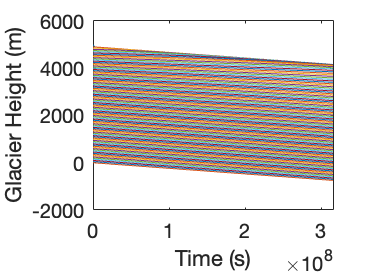

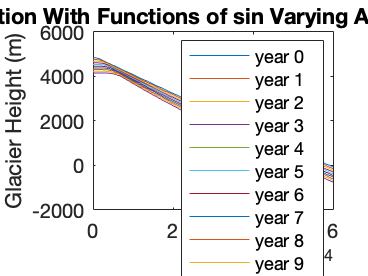

H = 	1.0e+03 *

    5.0000    4.8937    4.8966    4.8895    4.8833    4.8770    4.8707    4.8645    4.8582    4.8519    4.8456    4.8393    4.8331    4.8268    4.8205    4.8142    4.8080    4.8017    4.7954    4.7891    4.7829    4.7766    4.7703    4.7640    4.7578    4.7515    4.7452    4.7389    4.7326    4.7264    4.7201    4.7138    4.7075    4.7013    4.6950    4.6887    4.6824    4.6762    4.6699    4.6636    4.6573    4.6511    4.6448    4.6385    4.6322    4.6259    4.6197    4.6134    4.6071    4.6008
    4.9000    4.9029    4.8958    4.8896    4.8833    4.8770    4.8707    4.8645    4.8582    4.8519    4.8456    4.8393    4.8331    4.8268    4.8205    4.8142    4.8080    4.8017    4.7954    4.7891    4.7829    4.7766    4.7703    4.7640    4.7578    4.7515    4.7452    4.7389    4.7326    4.7264    4.7201    4.7138    4.7075    4.7013    4.6950    4.6887    4.6824    4.6762    4.6699    4.6636    4.6573    4.6511    4.6448    4.6385    4.6322    4.6259    4.6197    4.6134   

H = Up_euler(a_rate(k), "Functions of sin Varying")




% accumulation, we will run accumulation using 2 constant cases, one
% positive and one negative, and one with seasonal change


%Accumulation rate changes but stays positive
a_init = -.000005; %m/s
a_rate = a_init.*sin((t.*pi)./(500) + 0.03); 

%accumulation rate is constant
a_rate(1:length(t)) = a_init;

%we need a to be the same size as the result

function [H] = Up_euler(a, a_title)

%parameters
rho = 917;          % ice density kg/m^3
g = 9.81;             % gravity (m/s^2)
m = 3;                % constant from autumns last paper
A = 7*10^6;          % basal roughness, ask for value
beta = 1.5*10^-3;   %slope
alpha = beta;       %bed slope--> 

%time
year = 24*365*60*60; %year in seconds
month = year/12;%month in seconds
day = 24*60*60;  % seconds in a day
dt = month;
tf = 10*year; %time frame and also time final running 10 years
nt = tf/dt; %number of time steps
t = linspace(0,tf,nt);

%grid spacing
dx = 100; %meters, size of grid step
glacier_length = 60000; %length of our mountain glacier
x = linspace(0, glacier_length,dx);
nx = length(x);

%H initial!
len = 2:nx
h_init = 5000; %m
H = nan(nx,nt); 
H(2:end,1) = h_init - len.*(h_init/nx);  %this makes our glacier height linearly decline to 0!
H(1,1) = h_init; 

%accumulation
a_rate = a

for k = 1:nt-1
    %calulating U for each time step
    u = ((rho.*g.*H(:,k).*(alpha)).^m)./(A.^m);
%     Hprev = H(:,k);
%     H(:,k+1) = E_upwind(Hprev,dt,dx,u,a_rate(k));
    %setting up the M matrix
    M = spdiags([u*dt/dx.*ones(nx,1),1-(u*dt/dx).*ones(nx,1)],-1:0,nx,nx);
    %boundary conditions
    %height goes to 0 at the end of the glacier
    %we need an initial condition
    %set u value each time from last u value calculated
    
    M(end,end) = 1;
    M(end,end-1) = 0;
    M(1,1) = 0;
    M(1,2) = 1;

    H(:,k+1) = M*H(:,k)+a_rate*dt;
    %-a*v*dt
end
div = nt/10
plot(t, H)
xlabel('Time (s)');ylabel('Glacier Height (m)')
figure
plot(x, H(:,div))
hold on
plot(x, H(:,div*2))
plot(x, H(:,div*3))
plot(x, H(:,div*4))
plot(x, H(:,div*5))
plot(x, H(:,div*5))
plot(x, H(:,div*6))
plot(x, H(:,div*7))
plot(x, H(:,div*8))
plot(x, H(:,div*9))
plot(x, H(:,div*10))
xlabel('x (m)')
ylabel('Glacier Height (m)')
title('Advection With ' +a_title+ ' Accumuation' )
legend('year 0','year 1','year 2','year 3','year 4','year 5','year 6','year 7','year 8','year 9','year 10')
hold off


%checking to make sure that our matrix is correct
j = full(M);

end


## Results

#### What simulations did you run with the model?

Changed accumulation from constant to sin function (seasonal changes)

#### Describe the results.

#### How do the results compare with any known solutions, or data?

#### How do the results change with different methods, time steps, grid spacing, or model parameters?

#### What did the model tell you about the process you were studying?

#### How could the model be improved in terms of methods used or processes included?